# Code to Run on 4/30

clc        
% clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

## **Set up robot control system** ( code that runs once )

% Set up Raspberry Pi
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

note: It takes a 10 seconds or so to download code to Raspberry PI 


[robotPi, blinkLED]= RaspPiSetup()

robotPi =   raspi with properties:

         DeviceAddress: '192.168.33.177'              
                  Port: 18734                         
             BoardName: 'Raspberry Pi Model B+'       
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


blinkLED = 'led0'


% Turn on board LED on and off to signal program has started 
%Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

Warning! Robot Rover Active! 



% Set up servos, PiCam, and QWIIC analog input
[roverServos] = ServoSetup(robotPi)

ans = 1×5 cell array
    {'0x40'}    {'0x42'}    {'0x48'}    {'0x49'}    {'0x70'}


roverServos =   I2C_Servo_pHAT with properties:

                DEFAULT_I2C_BUS: 'i2c-1'
             DEFAULT_HW_ADDRESS: '0x40'
                   DEFAULT_NAME: "Pi Servo HAT"
        DEFAULT_SERVO_FREQUENCY: 50
    DEFAULT_SERVO_MAX_DUTYCYCLE: 0.5000
    DEFAULT_SERVO_MIN_DUTYCYCLE: 0.0750
         DEFAULT_SERVO_OP_ANGLE: 190
                         gcAddr: '0x00'
                         acAddr: '0x70'
                      subAddr_1: '0x71'
                      subAddr_2: '0x72'
                      subAddr_3: '0x74'
                         device: [1×1 raspi.internal.I2Cdev2]
                      servoAddr: [1×16 struct]
            SERVO_MAX_DUTYCYCLE: 0.5000
            SERVO_MIN_DUTYCYCLE: 0.0750
                 SERVO_OP_ANGLE: 190
                SERVO_FREQUENCY: 50


[robotCam] = PiCamSetup(robotPi)

robotCam =   cameraboard with properties:

                    Name: Camera Board   
              Resolution: '320x240'       (View available resolutions)
                 Quality: 10              (1 to 100)
                Rotation: 0               (0, 90, 180 or 270)
          HorizontalFlip: 0              
            VerticalFlip: 0              
               FrameRate: 30              (2 to 90)
               Recording: 0              

   Picture settings
              Brightness: 50              (0 to 100)
                Contrast: 0               (-100 to 100)
              Saturation: 0               (-100 to 100)
               Sharpness: 0               (-100 to 100)

   Exposure and AWB
            ExposureMode: 'sports'        (<a href="matlab

[adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)

rawRangeData1 =     0.7360    1.0600    0.2249    0.5783


rawRangeData2 =     0.0026    0.5783    0.6104    2.7627


[neo] = GPSSetup(robotPi)

**CREATE GLOBAL VARIABLES**

load final_waypoints.mat
speed = 1.42/3

speed = 0.4733

**CREATE MISSION DEFINITION FILE**

% Build list of desired behaviors for Mission 1
MDFOne = table(waypoints(:,1),waypoints(:,2))      % Build Mission Definition File (MDF) table

MDFOne = 30×2 table
     Var1      Var2  
    ______    _______

    42.293    -71.264
    42.293    -71.264
    42.293    -71.264
    42.293    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264


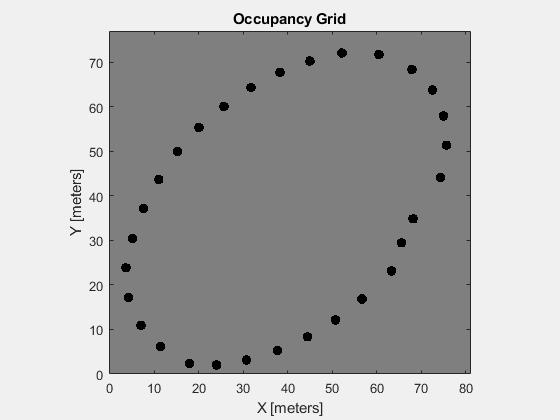

clf
res = 10; % resolution in cells per meter, so there are 10*10 = 100 cells in one meter
gridsize = [81 77];
roverOccupancyGrid = occupancyMap(gridsize(1), gridsize(2), res);

% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');   
    
p = 1;
for i = 1:length(waypoints)
    gridCoord = GPSToGrid(waypoints(i,:));
    updateOccupancy(roverOccupancyGrid,[gridCoord(1), gridCoord(2)],1);
end
inflate(roverOccupancyGrid, 1); % helps waypoints show up better

% Create free floating figure (Rover occupancy grid)
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);

radius = 11.9792

speed = 0.4733

newRoverLocation =     3.5998   18.4117


steeringAngle = 2.1000

distToTargetMeters = 12.1589

speed = 0.4733

newRoverLocation =     3.1188   19.7468


steeringAngle = 2.1000

distToTargetMeters = 10.9147

speed = 0.4733

newRoverLocation =     2.7990   21.1295


steeringAngle = 2.1000

distToTargetMeters = 9.6322

speed = 0.4733

newRoverLocation =     2.6451   22.5403


steeringAngle = 2.1000

distToTargetMeters = 8.3158

speed = 0.4733

newRoverLocation =     2.6590   23.9594


steeringAngle = 2.1000

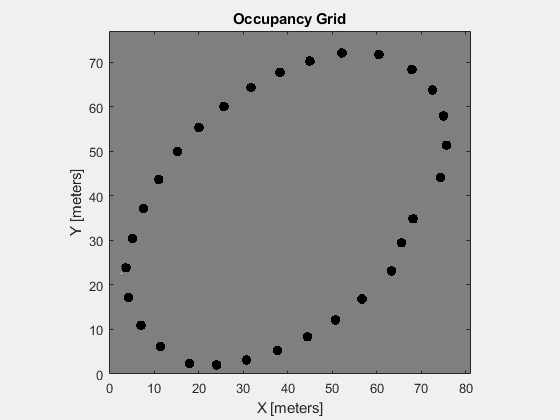

comSteer = 50;                       % set steering center
comSpeed = 50;                       % set drivespeed to zero
controlFlag = 1;                     % create a loop control
drivingSpeed = 44;


DriveRover(roverServos,0,0);   % act on the given steering angle

% start rover at first waypoint
roverLocation = waypoints(1,:);
roverLocation_grid = GPSToGrid(roverLocation);

%starting mission
waypoint = 3;
New_Rover_Locations = [];
while waypoint <=  3
    % Get Current Location
%     roverBearing = GetGPSBearing(neo)
    roverBearing = 330;
    
    % finding target waypoint
    targetWaypoint = [MDFOne{waypoint,1} MDFOne{waypoint,2}];
    targetWaypoint_grid = GPSToGrid(targetWaypoint);
    
    
    % distance between location and waypoint in meters
    distToTargetMeters = norm(roverLocation_grid-targetWaypoint_grid);
    dist_threshold = 1.5;% meters
    [circle_center,radius] = findCircle(roverLocation_grid, targetWaypoint_grid, roverBearing);    
   radius
    while distToTargetMeters > dist_threshold
        time_elapsed = 3;
        [roverLocation_grid, steeringAngle] = GoToWayPoint(roverOccupancyGrid,figureRoverOccupancy, targetWaypoint_grid, roverBearing, roverLocation_grid, circle_center,radius, time_elapsed);%        [steeringAngle] = roverArbiter(waypointSteeringVector)
        steeringAngle
        figure(figureRoverOccupancy);                            
        show(roverOccupancyGrid);

        tic
        while toc < time_elapsed
            DriveRover(roverServos,steeringAngle,drivingSpeed);   % act on the given steering angle
        end
        DriveRover(roverServos,steeringAngle,0);   % stop rover
        distToTargetMeters = norm(roverLocation_grid-targetWaypoint_grid)
    end
    disp("reached waypoint: ");
    waypoint
    waypoint = waypoint+1;
end

% shut down
DriveRover(roverServos,0,0);
% roverServos.setServoPWM(4,0);
% roverServos.setServoPWM(5,0);

pwm = AngleForServo(2)
DriveRover(roverServos,0,0);

 neo.getBasic;
 
 roverBearing = 0;
 for i = 1:5
     test = GetGPSBearing(neo);
     roverBearing = roverBearing + test;
 end
 roverBearing/5;
 

function [roverLocation, steeringAngle] = GoToWayPoint(roverOccupancyGrid,figureRoverOccupancy, targetWaypoint, roverBearing, roverLocation, circle_center,radius, time_elapsed)
    
    %    Initialize the waypoint vector
    waypointSteeringVector = zeros(71,1);
    
    % Do math to find radius of bumblebee circle -> put in function
       % experimenting with differentdriving intervals
    
    
    [m, b] = find_bearing_line(roverLocation, roverBearing);
    [turn_direction] = CW_or_CCW(targetWaypoint, m, b);
    
    [newRoverLocation] = updateRoverPosition(roverLocation, circle_center, radius, time_elapsed, turn_direction)
    
    updateOccupancy(roverOccupancyGrid, [newRoverLocation(1) newRoverLocation(2)], 0);
    figure(figureRoverOccupancy);
        show(roverOccupancyGrid); 

    roverLocation = newRoverLocation;
    
        
    % Calculate steering angle
    steeringAngle = (radius - 3.1595)./(-0.0702); % calibration (linear)
    if radius > 30
        steeringAngle = 0;
    elseif radius > 20
        steeringAngle = 0.3;
    elseif radius > 2.73
        steeringAngle = 2.1;
    end
    if turn_direction == "CCW"
        steeringAngle = -steeringAngle;
    end
%     a = .23;
%     b = 0.42;
%     c = .21;
%     steeringAngle = asind((2*b)/(2*radius+a+c))  % calibration (1/x)

    
end

**UPDATE ROVER LOCATION**

function [newRoverPosition] = updateRoverPosition(roverPosition_grid, circle_center, radius, time_elapsed, turn_direction)
    % find the location of the rover if we're rotating counterclockwise using this link:
        % https://math.stackexchange.com/questions/53875/calculating-point-around-circumference-of-circle-given-distance-travelled

%     speed = 2.14/5; %m/s
    speed = 1.42/3 %m/s
    dist_traveled = speed*time_elapsed;
    
    % TODO: figure out whether we're traveling clockwise or counterclockwise
    
    %center
    a = circle_center(1);
    b = circle_center(2);
    
    %current location of of rover
    x = roverPosition_grid(1);
    y = roverPosition_grid(2);
    r = radius;
    
    if turn_direction == "CCW"
        phi = dist_traveled/r;
    elseif turn_direction == "CW"
        phi = -dist_traveled/r;
    end
    
    newRoverPosition(1) = a+(x-a)*cos(phi) - (y-b)*sin(phi);   % circle math in radians
    newRoverPosition(2) = b+(x-a)*sin(phi) + (y-b)*cos(phi);
end

% TODO: Methods to try to find bearing
%     bearing = ((1/radius_meters)-0.05312)/0.03153;
%     bearing = bearing - 3;
%     if bearing < 0
%         bearing = 0;
%     end

    
    % converting to bearing
    % Calibration?
%     bearing = (radius_meters - 3.1595)./(-0.0702)
%     a = .23;
%     b = 0.42;
%     c = .21;
%     bearing = asind((2*b)/(2*radius_meters+a+c))
%     if radius_meters > 30
%             bearing = 0;
%         elseif radius_meters > 20
%             bearing = 0;
%     elseif 
%         elseif radius_meters > 2.73
%             bearing = 1;
%     end
%      
    % finding the index for the turn angles to change
%      bearing = (round(bearing))
%      turnAngles = -35:1:35; % 8 vectors( y range is from -1 to 1)
%      ind = find(abs(turnAngles - bearing) <= 0.001);
% 
%     % Change the steering vector
%     waypointSteeringVector(ind) = 0.5;
% end

function [roverBearing] = GetGPSBearing(neo) % this will be provided from canvas
    basic_data = neo.getBasic();
    roverBearing = basic_data.heading;
end

function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)];
     angles = [1 2 3 4 5; -pi/3 -pi/6 0 pi/6 pi/3]; % chagne this later     
     threshold = 40;
     for i = 1:5
        % voltage to distance     
        distance = (rawRangeData(i) - 2.805)/(-0.03316);
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation);
            updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        end   
     end  
end


function [obstaclePosX, obstaclePosY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
            omega = 360+omega;
    elseif omega > 360
        omega = omega-360;
    end
    quo = omega/90;
    modulo = mod(omega,90);
    if floor(quo) == 0 % Quadrant I
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    elseif floor(quo) == 1 % Quadrant IV
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 2 % Quadrant III
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 3 % Quadrant IV
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    end
end

function [roverOccupancyGrid] = SonarRange(roverOccupancyGrid, figureRoverOccupancy, headBearing, roverLocation, adcDevice1) % fill in other variables
% Mark obstacles based on the positions on the grid

    % Sonar calibration, covert voltage data into distance measurement (cm)
    distanceLeft = (adcDevice1.readVoltage(2)-0.01063)/0.01584; 
    distanceRight = (adcDevice1.readVoltage(3)-0.01063)/0.01584;
    
    % If measured distance is within some threshold, mark it as an obstacle
    % on the occupancy grid
    threshold = 5;
    if distanceLeft < threshold
        omegaLeft = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaLeft, distanceLeft, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        
    end
    if distanceRight < threshold 
        omegaRight = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaRight, distanceRight, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
    end
end



function[roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam,roverJoy, roverServos)
%% TODO for sonar function, headBearing == roverBearing + (panAngle converted to global bearing)
    
    joystickControl=1
    while joystickControl == 1
        % Use joystick to move rover head, Y + enter when ready to sense
        while 1
            [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
            DrivePanTilt(panAngle, tiltAngle, roverServos)
            stop=input('Ready to sense? type Y then hit enter ','s');
            if stop == 'Y'
                break
            end
        end
        % Call all the sense functions related to Mission 1
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2) % fill in other variable
%         [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
%         [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation, adcDevice1) % fill in other variables
       
        figure(figureRoverOccupancy);     % Show updated occupancy grid
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
        
        joystickControl=input('Keep sensing? (0-1)');
    end
end


function [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    panAngle = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    tiltAngle = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

**THINK FUNCTIONS**

function [steeringAngle] = roverArbiter(behavior1, behavior2, behavior3, behavior4, behavior5)
% From all the brainwaves generated from the different behaivoursav, output a final direction
    % If parameters are not given, default as vector of zeros
    num_behaviors = 5;
    switch nargin
        case 4
            behavior5 = zeros(1,71);
            num_behaviors = 4;
        case 3
            behavior4 = zeros(1,71);
            behavior5 = zeros(1,71);
            num_behaviors = 3;
        case 2
            behavior5 = zeros(1,71);
            behavior4 = zeros(1,71);
            behavior3 = zeros(1,71);
            num_behaviors = 2;
        case 1
            behavior5 = zeros(1,71);
            behavior4 = zeros(1,71);
            behavior3 = zeros(1,71);
            behavior2 = zeros(1,71);
            num_behaviors = 1;
    end    
    steeringVector = (behavior1 + behavior2 + behavior3 + behavior4 + behavior5)/num_behaviors;
    
    turnAngles =  -35:1:35; % 8 vectors( y range is from -1 to 1)
    
%     figure(figureArbiter)                 % go to brain waves figure
%     %clf                               % clear figure of old waves
%     plot(turnAngles, behavior1, "b-+");        % plot behaviour 1 waveform
%      ax=gca;
%      ax.XDir = 'reverse';
%     axis([-8 8 -8 8]);
%     grid on;
%     grid minor;
%     hold on
%     plot(turnAngles, behavior2, "g-+");
%     plot(turnAngles, behavior3, "c-o");
%     plot(turnAngles, behavior4, "y-o");
%     plot(turnAngles, behavior5, "b-o");
%     
%     plot(turnAngles, steeringVector, "r-+");       % plot sum of steer angle waveform
%     legend('behavior1','behavior2','behavior3','behavior4','behavior5') % label plot
%     hold off
    
    [x,ind] = max(steeringVector);
    steeringAngle = turnAngles(ind)    
end

function pwm = AngleForServo(angle)
pwm = ((angle + 85.21)/1.755) - 2.35;
end

function [turn] = leftorright_quad2(roverLocation, roverBearing, waypoint)  
    A = roverLocation;    
    point_x= roverLocation(1) + 2*cosd(roverBearing) % point 2
    point_y = roverLocation(2) + 2*sind(roverBearing)% point2
    B = [point_x point_y];
%     line_eq = k*x + n
%     P = (a,b)
    k = (A(2) - B(2))/(A(1) - B(1));
    n = A(2) - k*A(1);
    
    a = waypoint(1);
    b = waypoint(2);
    
   
    if k*a + n > b
        turn = 'right';
    elseif k*a + n < b
        turn = 'left';
    else
        turn = 'on the line';
    end
end

function [C]=circ_cent(P1,P2,R)
%Inputs:
    %P1-First point e.g. [3 4] => (x1,y1)
    %P2-Second point  
    %R-Radius
%Output:
    %C-Center of the circle. Its a 2x2 matrix. First row represents first 
    %possible center (x1,y1) and second row is the second possible center
    
    if(~(isreal(P1) && isreal(P2) && isreal(R)))
        error('Invalid/Complex inputs');
    end
    
        
    a=P1(1)^2-P2(1)^2;
    b=P1(2)^2-P2(2)^2;
    c=-2*(P1(1)-P2(1));
    d=-2*(P1(2)-P2(2));
    e=a+b;
    Coeff1=1+(d/c)^2;
    Coeff2=((2*d*e/c^2)+(P2(1)*2*d/c)-2*P2(2));
    Coeff3=((e/c)^2+(2*P2(1)*e/c)+P2(1)^2+P2(2)^2-R^2);
    All_coeff=[Coeff1 Coeff2 Coeff3];
    Eq_root=roots(All_coeff);
    C=zeros(length(Eq_root),2);
    for i=1:length(Eq_root)
        x=-(e+d*Eq_root(i))/c;
        C(i,1)=x;
        C(i,2)=Eq_root(i);
    end
    if(~isreal(C))
        error('Circle with the specified radius does not pass through specified points');
    end
end

**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle, roverServos)
     roverServos.setServoPWM(4,panAngle);    % commands panning servo
     roverServos.setServoPWM(5,tiltAngle);   % commands tilting servo
end

function [] = DriveRover(roverServos,direction,speed)
     servoAngle = AngleForServo(direction);
     roverServos.setServoPWM(1,servoAngle);      % commands steering servo
     roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

**SETUP PI**

function [robotPi, blinkLED] = RaspPiSetup()
%    robotPi = raspi('192.168.34.15', 'pi', 'raspberry');   % melody pi
   robotPi = raspi('192.168.33.177', 'pi', 'raspberry');   % melody pi
   blinkLED = robotPi.AvailableLEDs{1};
end

**SETUP SERVOS**

function [roverServos] = ServoSetup(robotPi)
% Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 
scanI2CBus(robotPi)

% Configure Servo pHAT driver board (address 0x40), set servos to null position.
roverServos = I2C_Servo_pHAT(robotPi);
pSteer = 1;                                   % set Steer servo to pin 1
pSpeed = 3;                                   % set Speed servo to pin 3
comSteer = 50;                                % set intial steer command to 0 angle
comSpeed = 50;                                % set intial speed command to 0 speed
roverServos.setServoPWM(pSteer,comSteer);     % Set sterring servo  center position
roverServos.setServoPWM(pSpeed,comSpeed);     % Set Rover speed  zero

% Define joystick ID (if only using 1 joystick, this will likely be '1')
% ID = 1;

% Create joystick variable
% roverJoy=vrjoystick(ID);

% Visualize the test servo commands in robot coordinate system.
% create a new free-standing figure to display the servo data, rover
% at center
localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
PlotServoSettings(localServoPlot,comSteer,comSpeed)
end

function [] = PlotServoSettings(localServoPlot,comSteer, comSpeed)
    % Plots Rover's steerig angle and speed on a stand alone figure
    figure(localServoPlot)
    plot(comSteer,comSpeed, 'r*');
    axis([30 70 30 70]);
    grid on;
    grid minor;
    xlabel('Actual Steer Servo Setpoint')
    ylabel ('Actual Speed Servo Setpoint')
    hold on;
    plot(50,50, 'g^');             % plot robot position 
    hold off;  
end


**SETUP PICAM**

function [robotCam] = PiCamSetup(robotPi)
% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorithms crazy by constantly changing
SetUpPiCamera(robotCam);
end

function []= SetUpPiCamera(robotCam)
    % creates and configures an Pi V2 Camera to be a simple robot 
    % vision system. It requires a standard Pi V2 cmaera attached to 
    % your Raspberry piand takes the picam object name as sole input
    % You need to set your cameras unique parameters to optimize picture
    % D. Barrett 2021 Rev A
    % Available resolutions: '160x120', '320x240', '640x480', '800x600', '1024x768', '1280x720', '1920x1080'
    % Available exposure modes: 'auto', 'night', 'nightpreview', 'backlight', 'spotlight', 'sports', 'snow', 
    % 'beach', 'verylong', 'fixedfps', 'antishake', 'fireworks'
    % Available AWB modes: 'off', 'auto', 'sun', 'cloud', 'shade', 'tungsten', 'fluorescent', 
    % 'incandescent', 'flash', 'horizon'
    % Available metering modes: 'average', 'spot', 'backlit', 'matrix'
    % Available image effects: 'none', 'negative', 'solarise', 'sketch', 'denoise', 
    % 'emboss', 'oilpaint', 'hatch', 'gpen', 'pastel', 'watercolour', 'film', 'blur', 'saturation', 'colourswap', 'washedout', 'posterise', 'colourpoint', 'colourbalance', 'cartoon'

    % Fix  exposure set it to respond quickly, set auto whitebalance to off
    robotCam.ExposureMode = 'sports';
    robotCam.AWBMode = 'fluorescent';
end


**SETUP QWIIC ANALOG INPUT**

function [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48'); % 2 sonar sensor and 2 IR
adcDevice2 = ads1015(robotPi,'i2c-1','0x49'); % 3 IR sensors

rawRangeData1 = SENSE_ADC(adcDevice1)
rawRangeData2 = SENSE_ADC(adcDevice2)
rawRangeData = [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together
% Visualize the test sensor scan data in robot coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
PlotSensorData(localSensorPlot, rawRangeData);
end

function [] = PlotSensorData(localSensorPlot, rawRangeData)
    % Plots Rover Sensor Data on a standalone figure
    figure(localSensorPlot)
    plot(rawRangeData)
    axis([1 8 0 3.5]);
    grid on;
    grid minor; 
    xlabel('Sensor Station')
    ylabel ('Raw Sensor Voltage')
    hold on;
    plot(4.5,0, 'r*');             % plot robot position 
    hold off;  
end


**SETUP GPS**

function [neo] = GPSSetup(robotPi)
neo = NEO_M8U(robotPi);            % Create a GPS Class Instance
pause(2);                          % Let GPS get up to speed
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
end

**SETUP JOYSTICK**

function [roverJoy] = JoystickSetup(joystickID)
 % Create joystick variable
   roverJoy=vrjoystick(ID);
end

**JACKIE'S FUNCTIONS**

all math for this function done in meters

**CIRCLE MATHS**

function [circle_center, radius] = findCircle(roverLocation, targetWaypoint, roverBearing)   
    %% find the equation of the circle given line and two points
    
    % find the equation of the line that i
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [m, c] = find_line(roverLocation, roverBearing);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %y =  mx +  c
    %ax + by +  d = 0
    %mx - y +   c = 0
    a = m;
    b = -1;
    d = c;
    
    % equation of a circle
    % x2+y2+2gx+2fy+c=0 (-g,-f) is the center
    x1 = roverLocation(1); y1 = roverLocation(2);
    x2 = targetWaypoint(1); y2 = targetWaypoint(2);
    syms g f c
    eqn1 = x1^2 + y1^2 + 2*g*x1 + 2*f*y1 + c == 0;
    eqn2 = x2^2 + y2^2 + 2*g*x2 + 2*f*y2 + c == 0;
    
    % substitute g and f into the equation of the line
    eqn3 = a*-g + b*-f + d == 0;
    
    % solving the three equations
    sol = solve([eqn1, eqn2, eqn3], [g, f, c]);
    G = sol.g;
    F = sol.f;
    C = sol.c;
    
    % assigning the circle center
    circle_center = double([-G, -F]);
    
    % finding the radius
    radius = norm(circle_center - roverLocation);
        
    %plotting
    hold on
        viscircles(circle_center,radius);
        plot(circle_center(1),circle_center(2),'gx',"MarkerSize",20, 'DisplayName','circleCenter')
        plot(targetWaypoint(1),targetWaypoint(2),'kx','MarkerSize',20, 'DisplayName','targetWaypoint')
        plot(roverLocation(1),roverLocation(2),'bx','MarkerSize',20, 'DisplayName', "roverLocation")
    hold off
    legend("Location", 'southoutside')
    axis equal
end

function [m, b] = find_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1);
    y = roverPosition(2);
    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        omega = mod(roverBearing+90, 90);
        omega = 90 - omega;
        a = abs(y*tand(omega));
        x_int = a+x;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        omega = mod(roverBearing+90, 90);
        a = abs(y*tand(omega));
        x_int = x-a;
    end
    m = (y-0)/(x-x_int);
    b = y-m*x;

    % plotting
%     
    hold on
    x= linspace(x-5,x+5, 10);
    y= m*x + b;
    
    plot(x, y, 'b', 'DisplayName','center line')
    axis equal
    hold off
end

function [m, b] = find_bearing_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1);
    y = roverPosition(2);
    omega = mod(roverBearing, 90);

    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        a = abs(y*tand(omega));
        x_int = x-a;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        omega = 90-omega;
        a = abs(y*tand(omega));
        x_int = x+a;
    end
    m = (y-0)/(x-x_int);
    b = y-m*x;
    
    hold on
    x= linspace(x-5,x+5, 10);
    y= m*x + b;
    
    plot(x, y, 'r', 'DisplayName','bearing line')
    axis equal
    hold off

end

function [direction] = CW_or_CCW(targetWaypoint, m, b)
    pt_on_line = (targetWaypoint(2) - b)/m; % x coord of point of projected waypoint on rover bearing line
    if pt_on_line < targetWaypoint(1)
        direction =  "CW";
    else
        direction =  "CCW";
    end
end


**GPS COORDS TO GRID COORDS**

function [gridCoordinate] = GPSToGrid(GPSCoordinate)
    altitude = 10;
    % origin is at the bottom left corner
    origin = [42.29313067072105, -71.26442435650652, altitude];
    [gridCoordinate(1),gridCoordinate(2)] = latlon2local(GPSCoordinate(1), GPSCoordinate(2),altitude,origin);
end

function GetOutOfDock(roverServos,drivingSpeed)
% some initial code to get out of the dock
% tic
% while toc < 3
%     % drive straight and forward
%     angle = AngleForServo(0)
%     angle = round(angle)
%     DriveRover(roverServos,angle,drivingSpeed);    
% end
% while toc < 3
%     % drive left and forward
%     angle = AngleForServo(-20)
%     angle = round(angle)
%     DriveRover(roverServos,angle,drivingSpeed);    
% end
end